disp('============IDENTIFICAÇÃO CONVERSOR BUCK (bancada)============');

============IDENTIFICAÇÃO CONVERSOR BUCK (bancada)============


disp('Dados ensaio: 20KHz ; Ts = 50us');

Dados ensaio: 20KHz ; Ts = 50us


disp('Laboratorio LINCE');

Laboratorio LINCE


disp('Discente: Luiz Felipe Souza de Lima Silva');

Discente: Luiz Felipe Souza de Lima Silva


1. Inicialização e declaração de parametros:

clear, clc, close all
dados_csv = readmatrix('Dadosensaio_prbs500us.csv');

Nd = 500;
Ts = 5.0e-5; 

disp('------------------------------------------------------');

------------------------------------------------------


disp('PARAMETROS DE PROJETO:');

PARAMETROS DE PROJETO:



Fs = 20000

Fs = 20000

d =  0.3

d = 0.3000

Vs = 30

Vs = 30

Cp = 0.000041666667

Cp = 4.1667e-05

L = 0.000470

L = 4.7000e-04

R = 10.0

R = 10

num = Vs/(Cp*L);
den = [1,1/(Cp*R) , 1/(Cp*L)];

2. Função de transferencia matematica:

disp('------------------------------------------------------');

------------------------------------------------------


disp('FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:');

FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:



Gs = tf(num,den)

Gs =
 
         1.532e09
  -----------------------
  s^2 + 2400 s + 5.106e07
 
Continuous-time transfer function.
Model Properties



disp('Polos e zeros:');

Polos e zeros:



pole(Gs)

ans = 1.0e+03 *

  -1.2000 + 7.0444i
  -1.2000 - 7.0444i



disp('Resposta ao Degrau:');

Resposta ao Degrau:


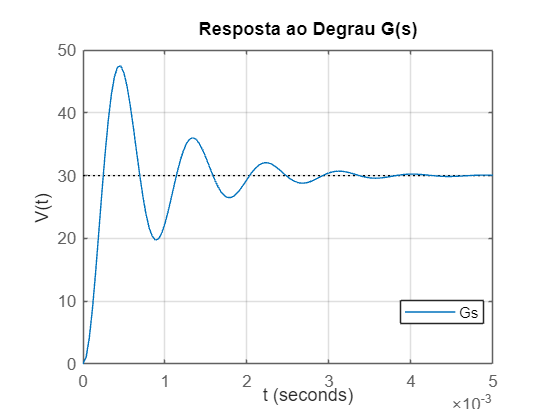

figure(1)
clf;
step(Gs)
xlabel('t'); ylabel('V(t)');
grid on; legend('Location', 'best');
title('Resposta ao Degrau G(s)') 


disp('Discretização de G(s) utilizando método "matched":');

Discretização de G(s) utilizando método "matched":


Gz = c2d(Gs, Ts ,'zoh')

Gz =
 
     1.821 z + 1.749
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


3. Coleta de dados e Identificação:

disp('COLETA DE DADOS E IDENTIFICAÇÃO:');

COLETA DE DADOS E IDENTIFICAÇÃO:


t = dados_csv(1:end-Nd, 1)'; %tempo
u = dados_csv(Nd:end-1, 2)'; %PRBS
v = dados_csv(Nd:end-1, 3)'; %Saída

mu_u = mean(u);
mu_v = mean(v);
u = u - mu_u;
v = v - mu_v;

y = transpose(v); 

disp('OBS.:Entrada num conjunto de 200 amostras.');

OBS.:Entrada num conjunto de 200 amostras.


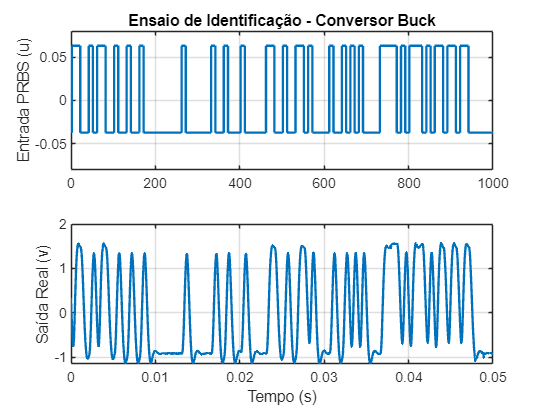

figure(2);
clf; 
subplot(2,1,1);
stairs(1:length(u), u, 'LineWidth', 1.4);
ylabel('Entrada PRBS (u)');
title('Ensaio de Identificação - Conversor Buck');
xlim([0 1000]);   
ylim([-0.08 0.08]); 
grid on;

subplot(2,1,2);
plot(t(1:length(v)), v, 'LineWidth', 1.4);
ylabel('Saída Real (v)');
xlabel('Tempo (s)');
grid on;


%% Construção matricial - regressores
Ns = numel(t);

M = zeros(Ns-3,4);

for n = 3:Ns
    phi = [y(n-1), y(n-2), u(n-1), u(n-2)];
    M(n, :) = phi;
end

theta = M\y;
a1 = theta(1);
a2 = theta(2);
b1 = theta(3);
b2 = theta(4);
ys = zeros(size(y));
ys(1:2) = y(1:2);

yp = M * theta;

disp('MODELO ARX OBTIDO:');

MODELO ARX OBTIDO:


Be = [0, b1, b2];
Ae = [1, -a1, -a2]; 
Gze = tf(Be, Ae, Ts)

Gze =
 
    0.09151 z + 0.5443
  ----------------------
  z^2 - 1.847 z + 0.8815
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


4. Analise e comparação de modelos:

disp('ANALISE E COMPARAÇÃO DE MODELOS:');

ANALISE E COMPARAÇÃO DE MODELOS:


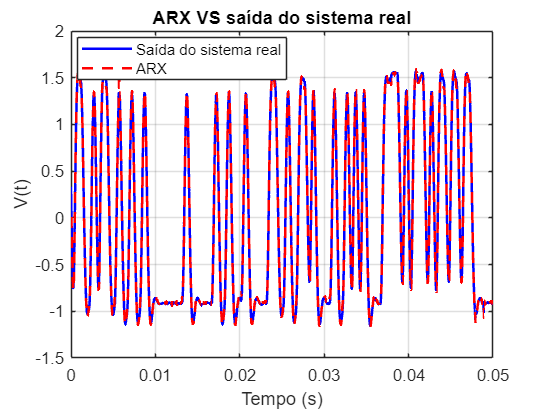

figure(3);
clf; 
plot(t, y, 'b', 'LineWidth', 1.5)
hold on

plot(t, yp, 'r--', 'LineWidth', 1.5)

legend('Saída do sistema real', 'ARX', 'Location', 'best');
hold off
grid on
xlabel('Tempo (s)');
ylabel('V(t)');
title('ARX VS saída do sistema real');
xlim([0 0.05]);    %maximo de 50us
ylim([-1.5 2]); 


disp('Funções de transferencia:');

Funções de transferencia:


disp('Gz modelo analitico');

Gz modelo analitico


Gz

Gz =
 
     1.821 z + 1.749
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties



disp('Gze modelo estimado');

Gze modelo estimado



Gze

Gze =
 
    0.09151 z + 0.5443
  ----------------------
  z^2 - 1.847 z + 0.8815
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


5.Ajuste R2:

disp('AJUSTE R2:');

AJUSTE R2:


R2 = 1 - sum((y - yp).^2)/sum((y - mean(y)).^2)

R2 = 0.9989

disp('------------------------------------------------------');

------------------------------------------------------


6. Cálculo do erro de predição/resíduo:

disp('Cálculo do erro de predição/resíduo:');

Cálculo do erro de predição/resíduo:


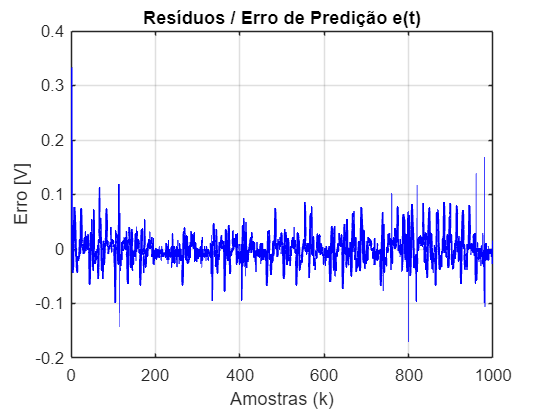

e = y - yp;

figure(6);
clf;
plot(e, 'b', 'LineWidth', 1.2);
grid on;
title('Resíduos / Erro de Predição e(t)');
xlabel('Amostras (k)');
ylabel('Erro [V]');

disp('------------------------------------------------------');

------------------------------------------------------


7. Analise de polos e zeros:

disp('ANALISE DE POLOS E ZEROS:');

ANALISE DE POLOS E ZEROS:



disp('BLUE - GZ');

BLUE - GZ


disp('RED - GZe');

RED - GZe


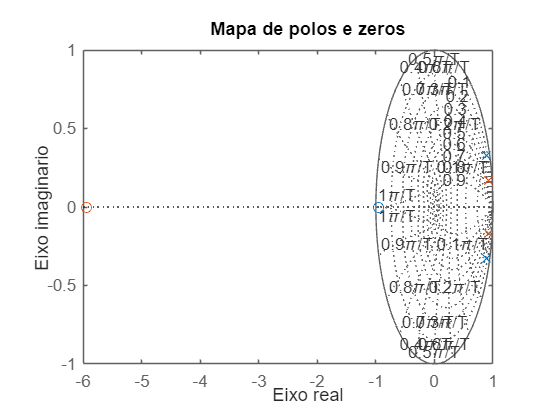


figure(7)
clf;
pzmap(Gz)
zgrid
hold on

pzmap(Gze)
hold off

xlabel('Eixo real');
ylabel('Eixo imaginario');
title('Mapa de polos e zeros');

disp('------------------------------------------------------');

------------------------------------------------------


8. Resposta ao degrau:

disp('resposta ao degrau Modelo discreto analitico');

resposta ao degrau Modelo discreto analitico


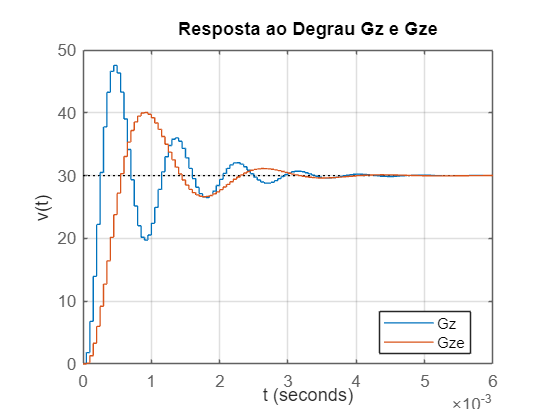


Ganho_Gz = dcgain(Gz);
Ganho_Gze = dcgain(Gze);
K_corr = Ganho_Gz / Ganho_Gze; 
Gze = Gze * K_corr;

figure(6)
clf;
step(Gz, Gze)
xlabel('t'); ylabel('v(t)');
grid on; 
legend('Gz', 'Gze', 'Location', 'best');
title('Resposta ao Degrau Gz e Gze');

disp('------------------------------------------------------');

------------------------------------------------------


9. Diagrama de Bode:

figure(7);
disp('Diagrama de Bode:');

Diagrama de Bode:


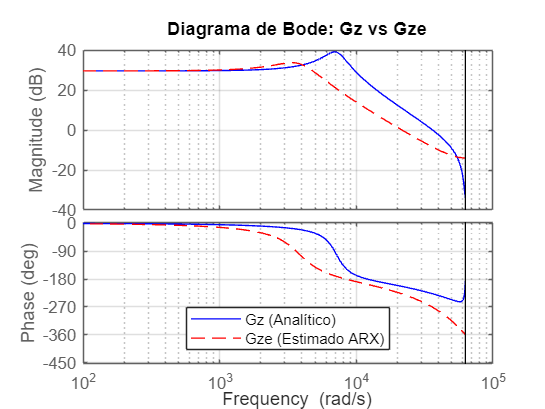

clf;
bode(Gz, 'b', Gze, 'r--');
grid on;
legend('Gz (Analítico)', 'Gze (Estimado ARX)', 'Location', 'best');
title('Diagrama de Bode: Gz vs Gze');

disp('------------------------------------------------------');

------------------------------------------------------


10. Projeto Controlador RST (discreto)

disp('============ PROJETO CONTROLADOR RST ============');

============ PROJETO CONTROLADOR RST ============



% A planta para o controlador será o modelo ARX
A = Ae; 
B = Be; 
b1_rst = B(2);
b2_rst = B(3);

Hs = [1, -1];
Al = conv(A, Hs);
a_1 = Al(2); a_2 = Al(3); a_3 = Al(4);


% --- ELABORAÇÃO AUTOMÁTICA DO POLINÔMIO P(q^-1) ---
zeta_d = 0.8;      % Coeficiente de amortecimento
wn_d = 5000;       % Frequência natural desejada [rad/s]

% Polos Dominantes 
p1_d = -2 * exp(-zeta_d * wn_d * Ts) * cos(wn_d * Ts * sqrt(1 - zeta_d^2));
p2_d = exp(-2 * zeta_d * wn_d * Ts);
PD = [1, p1_d, p2_d];

polo_aux = 0.1;
PF = conv([1, -polo_aux], [1, -polo_aux]);

P = conv(PD, PF);

% --- RESOLUÇÃO DA EQUAÇÃO DE BEZOUT (Matriz de Sylvester) ---
M_syl = [ 1,   b1_rst, 0,      0;
          a_1,  b2_rst, b1_rst, 0;
          a_2,  0,      b2_rst, b1_rst;
          a_3,  0,      0,      b2_rst ];

vetor_P = [ P(2) - a_1;
            P(3) - a_2;
            P(4) - a_3;
            P(5) ];
        
x_rst = M_syl \ vetor_P;

s1_rst = x_rst(1);
r0 = x_rst(2); 
r1 = x_rst(3); 
r2 = x_rst(4);

Sl = [1, s1_rst];               
S = conv(Sl, Hs);                
R = [r0, r1, r2];                
T = sum(P) / sum(B);             

disp('Polinômios do Controlador:');

Polinômios do Controlador:


fprintf(' S(q^-1) = 1 %+.4f q^-1 %+.4f q^-2\n', S(2), S(3));

 S(q^-1) = 1 -0.1419 q^-1 -0.8581 q^-2


fprintf(' R(q^-1) = %.4f %+.4f q^-1 %+.4f q^-2\n', R(1), R(2), R(3));

 R(q^-1) = 1.8572 -3.1940 q^-1 +1.4020 q^-2


fprintf(' T(q^-1) = %.4f\n\n', T);

 T(q^-1) = 0.0653



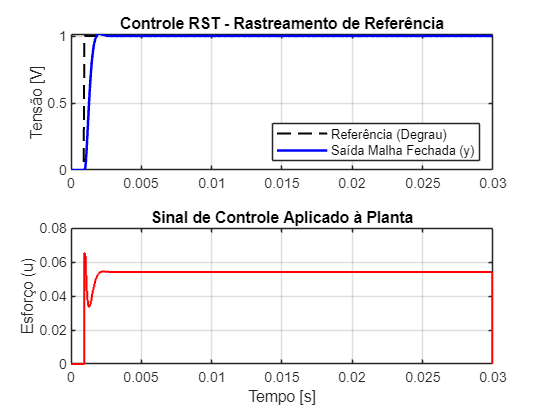


%% ========================================================================
% 11. SIMULAÇÃO EM MALHA FECHADA DO CONTROLADOR (Degrau)
% =========================================================================
N_sim = 600;
yr = zeros(1, N_sim);
yr(20:N_sim) = 1.0; % Degrau de referência unitário no instante k=20

y_mf = zeros(1, N_sim);
u_mf = zeros(1, N_sim);

for k = 3:N_sim-1
    % Lei de Controle RST: S u(k) = T yr(k+1) - R y(k)
    % A referência yr é tipicamente filtrada no instante futuro yr(k) (se d=0)
    u_mf(k) = -S(2)*u_mf(k-1) - S(3)*u_mf(k-2) ...
              + T*yr(k) ...
              - R(1)*y_mf(k) - R(2)*y_mf(k-1) - R(3)*y_mf(k-2);
          
    % Limitação do Sinal de Controle (Saturação do Duty Cycle do Buck)
    % Se a tensão limite ou duty cycle max/min existir, pode aplicar aqui.
    % if u_mf(k) > V_max; u_mf(k) = V_max; end
    % if u_mf(k) < V_min; u_mf(k) = V_min; end
    
    % Dinâmica da Planta Identificada
    y_mf(k+1) = -A(2)*y_mf(k) - A(3)*y_mf(k-1) + b1_rst*u_mf(k) + b2_rst*u_mf(k-1);
end

tempo_sim = (0:N_sim-1) * Ts;
    
figure(8); clf;
subplot(2,1,1);
plot(tempo_sim, yr, 'k--', 'LineWidth', 1.2); hold on;
plot(tempo_sim, y_mf, 'b', 'LineWidth', 1.5);
grid on; ylabel('Tensão [V]');
legend('Referência (Degrau)', 'Saída Malha Fechada (y)', 'Location', 'SouthEast');
title('Controle RST - Rastreamento de Referência');

subplot(2,1,2);
stairs(tempo_sim, u_mf, 'r', 'LineWidth', 1.2);
grid on; xlabel('Tempo [s]'); ylabel('Esforço (u)');
title('Sinal de Controle Aplicado à Planta');


disp('Simulação em malha fechada concluída e gráficos gerados.');

Simulação em malha fechada concluída e gráficos gerados.
